# `MATH 3620 Numerical Analysis`

# `Homework 10`

# `29 April 2021`

close all; clear all ; clc;

## `1a Newton's Method`

% function and its derivative
f = @(x) x.^3 - 5;
df = @(x) 3*x.^2;

% root
xr = 5^(1/3);

% Newton's method
x = 1; % initial guess, such that f'(x) is not zero
tol = 1e-6; % tolerance
iter = 0; % iteration counter
logerrors = [];
while abs(f(x)) > tol
    iter = iter + 1;
    x1 = x - f(x)/df(x);
    logerrors = [logerrors; log(abs(x1-xr)) log(abs(x - xr))];
    x = x1;
end

% display results
fprintf('The obtained solution is x = %g', x)

The obtained solution is x = 1.70998

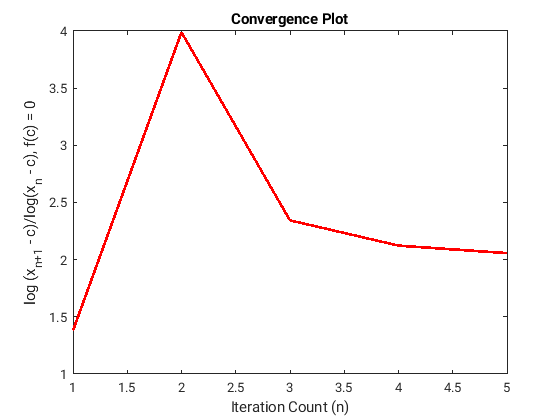


% plot convergence
plot(1:iter, logerrors(:, 1)./logerrors(:, 2), 'r-', 'LineWidth', 2);
xlabel('Iteration Count (n)')
ylabel('log (x_{n+1} - c)/log(x_n - c), f(c) = 0')
title('Convergence Plot')

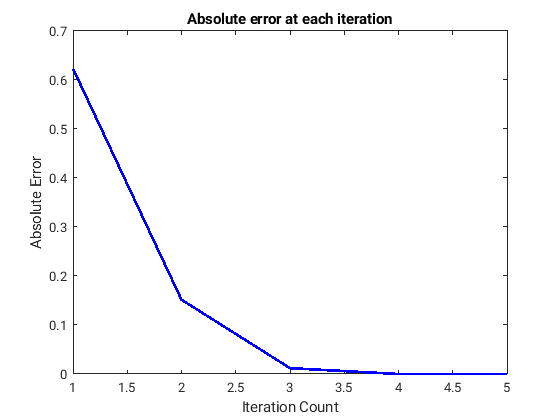

% plot iteration vs error
plot(1:iter, exp(logerrors(:, 1)), 'b-', 'LineWidth', 2)
xlabel('Iteration Count')
ylabel('Absolute Error')
title('Absolute error at each iteration')

`The convergence rate is 2 as expected from Newton's Method and is verified by the convergence plot. The errors decay at every iteration and hence, the obtained root is accurate.`

## `1b Fixed Point Iteration`

% function and its derivative
f = @(x) x.^3 - 5;
df = @(x) 3*x.^2;

% root
xr = 5^(1/3);

% Fixed point iteration
x = 1; % initial guess
tol = 1e-6; % tolerance
iter = 0; % iteration counter
logerrors = [];
while abs(f(x)) > tol
    iter = iter + 1;
    x1 = (2*x + 5/(x^2))/3;
    logerrors = [logerrors; log(abs(x1-xr)) log(abs(x - xr))];
    x = x1;
end

% display results
fprintf('The obtained solution is x = %g', x)

The obtained solution is x = 1.70998


% plot convergence
plot(1:iter, logerrors(:, 1)./logerrors(:, 2), 'r-', 'LineWidth', 2);
xlabel('Iteration Count (n)')
ylabel('log (x_{n+1} - c)/log(x_n - c), f(c) = 0')
title('Convergence Plot')


% plot iteration vs error
plot(1:iter, exp(logerrors(:, 1)), 'b-', 'LineWidth', 2)
xlabel('Iteration Count')
ylabel('Absolute Error')
title('Absolute error at each iteration')

`The convergence rate for the fixed point iteration is 2, the same as Newton's method. The method is accurate as well, as the errors decay to zero.`

## `1c`

`The iteration vs error plots have been plotted above.`

## `2a Centered Difference Approximation`

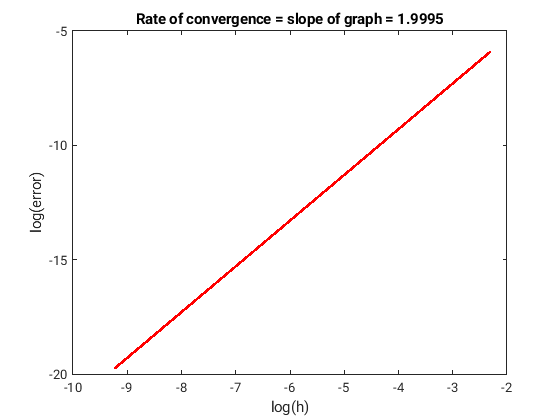

% function and its derivative
f = @(x) exp(x);
df = @(x) exp(x);

% step size 
n = 0:10;
h = 0.1./(2.^n);

% compute the centered difference approximation
p = 0.5;
Df = (f(p + h) - f(p - h))./(2*h);

% verify quadratic rate of convergence
slope = (log(abs(Df(end) - f(p))) - log(abs(Df(end - 1) - f(p))))/(log(h(end)) - log(h(end - 1)));
plot(log(h), log(abs(Df - f(p))), 'r-', 'LineWidth', 2)
xlabel('log(h)')
ylabel('log(error)')
titlestring = ['Rate of convergence = slope of graph = ', num2str(slope)];
title(titlestring)

`As can be seen from the plot, the slope is 1.9995 which is close to 2. Hence, the quadratic rate of convergence is verified.`

## `2b 'h' for minimum error`

% begin with h = 0.1
h = 0.1;

% point at which derivative is to be computed
p = 0.5;

% obtain optimal h
minerror = 1e3;
while (true)
    % computer error
    M3 = exp(x+h); % M3 = max(f''')
    aerror = (1/6)*h*h*M3; % truncation error
    rerror = abs(exp(p))*eps/h; % roundoff error
    err = aerror + rerror;
    % check if error reduces
    if err < minerror
        minerror = err;
    else
        break; % exit when error begins to increase
    end
    h = h/2; % update h for next iteration
end

h = 2*h;
fprintf('Least error is obtained with h = %g', h)

Least error is obtained with h = 6.10352e-06

Df = (f(p + h) - f(p - h))./(2*h);
fprintf('Value of derivative at %g with h = %g equals %1.15f.', p, h, Df)

Value of derivative at 0.5 with h = 6.10352e-06 equals 1.648721270721580.


% verify with analytical answer
M3 = exp(p);
hopt = (3*eps*abs(exp(p))/ M3)^(1/3);
fprintf('Expected optimal value of h = %g', hopt)

Expected optimal value of h = 8.73348e-06

`We can see that the analytical value of `$h_0$` is very close to the value of `$h_0$ `obtained numerically. Also `$h_0 \in [10^{-6}, 10^{-5}]$ `as expected since `$h_0 \approx c\text{eps}^{1/3}, \text{ eps } = 10^{-16}$`.`

## `2c Richardson Extrapolation`

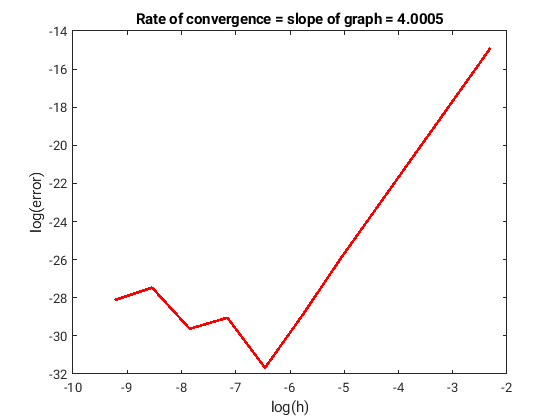

% function and its derivative
f = @(x) exp(x);
df = @(x) exp(x);

% step size 
n = 0:10;
h = 0.1./(2.^n);

% compute the centered difference approximation
p = 0.5;
Df1 = (f(p + h) - f(p - h))./(2*h);

% apply Richardson extrapolation
Df2 = (f(p + h/2) - f(p - h/2))./(2*h/2);
Df = (4*Df2 - Df1)/3;

% verify rate of convergence (= 4)
slope = (log(abs(Df(5) - f(p))) - log(abs(Df(4) - f(p))))/(log(h(5)) - log(h(4)));
plot(log(h), log(abs(Df - f(p))), 'r-', 'LineWidth', 2)
xlabel('log(h)')
ylabel('log(error)')
titlestring = ['Rate of convergence = slope of graph = ', num2str(slope)];
title(titlestring)

% identify h with least error
logerrors = log(abs(Df - f(p)));
[~, index] = min(logerrors);
hopt = h(index);

fprintf('Least error is obtained with h = %g', hopt)

Least error is obtained with h = 0.0015625

fprintf('Value of derivative at %g with h = %g equals %1.15f.', p, hopt, Df(index))

Value of derivative at 0.5 with h = 0.0015625 equals 1.648721270700146.


% verify with analytical answer
fprintf('Expected optimal value of h = O(1e-3)')

Expected optimal value of h = O(1e-3)

`We can see that the value of h that gives the least error is indeed of O(1e-3) as expected with a machine precision of eps = 1e-16.`

`Also, the convergence rate is indeed 4 as expected, when we look at the part of graph when errors continue to decrease. `

## `2d Composite Trapezoidal Rule`

% discretize theta
theta = linspace(0, 2*pi, 50);

% use composite trapezoidal rule to compute the derivative
p = 0.5; r = 2;
g = @(theta) f(p + r*exp(1i*theta)).*exp(-1i*theta);
h = theta(2) - theta(1);
integral = (h/2)*(g(0) + g(2*pi) + sum(2*g(theta(2:end-1))));
Df = integral/(2*pi*r);

% display results
fprintf('Using Integral Theorem and CTR with h = %g, the derivative equals %1.15f', h, Df)

Using Integral Theorem and CTR with h = 0.128228, the derivative equals 1.648721270700128

fprintf('Actual value of derivative = %1.15f', exp(1/2))

Actual value of derivative = 1.648721270700128

`We can see that the obtained value using Cauchy's Integral Theorem and Composite Trapezoidal Rule is correct to machine precision as expected.`